# Introduction to Clustering

An introduction to the theory behind clustering and an example showing how it can be applied.

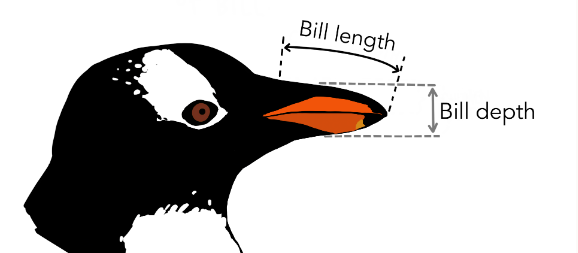

*Artwork by @allison_horst*

## Before you get started

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is clustering?

The term *clustering *refers to the action of grouping data and finding hidden patterns within it. Essentially, its goal is to partition a set of data into *clusters*, or collections of data points which are similar to the other data within their cluster, and dissimilar to the data in other clusters.

  **Try**. Click the "Run" button below to view an example of a clustering problem.

ShowClustering; 
% Set seed and boolean for random number generation in the next section
rng(3);
FirstRun = true;

### **How does clustering fit into the broader machine learning landscape?**

To understand where clustering fits under the umbrella of machine learning, there are a few key terms that are necessary to define:

With these definitions in mind, the following diagram depicts how clustering is differentiated from other common types of machine learning tasks:

[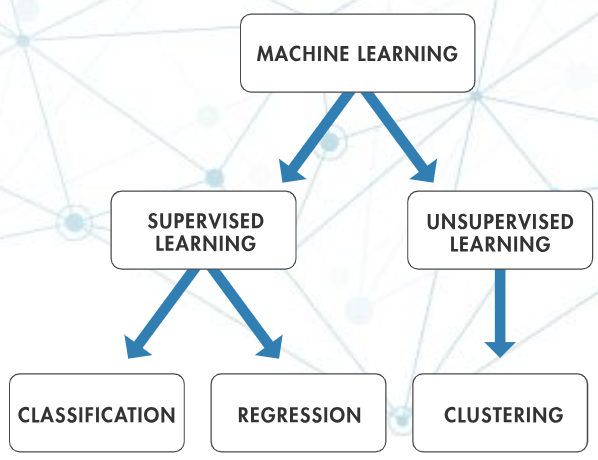](https://www.mathworks.com/solutions/machine-learning.html)

Notice that in the animation in the previous section, all of the data points are initially the same color - this is because the data is *unlabeled*. After the algorithm is applied, however, the data is split into two clusters, shown by the coloring of each data point. This is an example of an *unsupervised learning *problem.

 **Reflect**. Can you think of any real-life applications where clustering might be particularly useful? Think about situations where it may not be possible to obtain *labeled* data.

## **One method of clustering: k-means**

The most commonly used clustering algorithm, k-means is a method in which there are *k* clusters. As the name of the algorithm implies, each of the *k* clusters is defined by its mean, or *centroid*. The algorithm proceeds as follows:

- Select *k* points as the initial centroids of the clusters. These can be selected randomly or by hand.

- Assign each data point to its closest centroid. Closeness can be defined using a variety of distance measurements, some of which you will see below.

- Re-compute the centroids by calculating the mean of all the points in each cluster. In other words, update the locations of the centroids based on their assigned data points from step 2.

- Repeat steps 2 and 3 until the algorithm *converges* (until repeating steps 2 and 3 no longer changes the results of the algorithm).

** Demonstration**. Let's walk through a simple example of the k-means algorithm, where we want to assign 30 data points to 2 clusters (k = 2). We'll start by plotting 30 random data points which will serve as our data set:

 

RandData = rand(2,30) * 10;
scatter(RandData(1,:), RandData(2,:), 25, 'filled');
title("k-means Example");
% Set seed and boolean for random number generation in the next section
if FirstRun
    rng(5);
    FirstRun = false;
end

  **Try**. Before we begin applying the k-means algorithm to this data, try to identify where you think the cluster centers are. Click the button below to take your guesses, and later we'll compare them to the results of k-means:

 

scatter(RandData(1,:), RandData(2,:), 25, 'filled');
title("Your Guesses");
for i = 1:2
    [xGuesses, yGuesses] = ginput(1);
    hold on;
    scatter(xGuesses, yGuesses, 100, '*', "SeriesIndex", 7);
end
hold off;

  **Try**. Now that we have our data, we need to execute the first step of k-means, which is to select the initial centroids for our clusters. Let's select them randomly and add them to our plot:

 

scatter(RandData(1,:), RandData(2,:), 25, 'filled');
title("k-means Example");

CentroidB = rand(1,2) * 10;
CentroidR = rand(1,2) * 10;

if exist("cB","var") && exist("cR","var")
    try
    cB.XData = CentroidB(1);
    cB.YData = CentroidB(2);
    cR.XData = CentroidR(1);
    cR.YData = CentroidR(2);
    catch ME
        clear cB cR
            hold on;
    cB = scatter(CentroidB(1), CentroidB(2), 100, '*',"SeriesIndex",4);
    cR = scatter(CentroidR(1), CentroidR(2), 100, '*',"SeriesIndex",5);
    hold off;
    end
else
    hold on;
    cB = scatter(CentroidB(1), CentroidB(2), 100, '*',"SeriesIndex",4);
    cR = scatter(CentroidR(1), CentroidR(2), 100, '*',"SeriesIndex",5);
    hold off;
end

  **Pro-tip**. Always make sure that your initial centroids are reasonably close to the data (for this example, they were randomly placed such that the X and Y coordinates of the centroids are between the smallest and largest values in the data set). What would happen if one of the initial centroids was placed very far from the data? 

  **Try**. The next step is to assign each point to its closest centroid. Here, we'll use [Euclidean distance](https://en.wikipedia.org/wiki/Euclidean_distance) to determine closeness. Let's see how our data looks after being assigned to clusters:

 

DistsB = pdist2(RandData', CentroidB, 'euclidean');
DistsR = pdist2(RandData', CentroidR, 'euclidean');
ClusterB = RandData(:, DistsB <= DistsR);
ClusterR = RandData(:, DistsR < DistsB);

hold on;
scatter(ClusterB(1,:), ClusterB(2,:), 'filled', "SeriesIndex", 4, "SizeData", 25);
scatter(ClusterR(1,:), ClusterR(2,:), 'filled', "SeriesIndex", 5, "SizeData", 25);
hold off;

  **Try**. Now, we need to re-compute our centroids to be the means of their assigned data points. Let's see where our new centroids are located:

 

if ~isempty(ClusterB)
    CentroidB = mean(ClusterB, 2)';
end
if ~isempty(ClusterR)
    CentroidR = mean(ClusterR, 2)';
end
cB.XData = CentroidB(1);
cB.YData = CentroidB(2);
cR.XData = CentroidR(1);
cR.YData = CentroidR(2);

  **Try**. Now all that's left to do is repeat the last two steps until the algorithm converges. Click the button below to complete that process and see what the result looks like:

 

hold on;
for i = 1:10
    DistsB = pdist2(RandData', CentroidB, 'euclidean');
    DistsR = pdist2(RandData', CentroidR, 'euclidean');
    ClusterB = RandData(:, DistsB <= DistsR);
    ClusterR = RandData(:, DistsR < DistsB);
    
    scatter(ClusterB(1,:), ClusterB(2,:), 'filled', "SeriesIndex", 4, "SizeData", 25);
    scatter(ClusterR(1,:), ClusterR(2,:), 'filled', "SeriesIndex", 5, "SizeData", 25);

    CentroidB = mean(ClusterB, 2)';
    CentroidR = mean(ClusterR, 2)';
    cB.XData = CentroidB(1);
    cB.YData = CentroidB(2);
    cR.XData = CentroidR(1);
    cR.YData = CentroidR(2);

    drawnow;
end
hold off;

 **Reflect**. Was the result similar to the one you predicted? Use the button below to reveal how similar your guess was to the outcome of k-means:

 

hold on;
LabelKmeans = scatter(CentroidB(1), CentroidB(2), 100, '*', "SeriesIndex", 6);
scatter(CentroidR(1), CentroidR(2), 100, '*', "SeriesIndex", 6);
LabelUser = scatter(xGuesses, yGuesses, 100, '*', "SeriesIndex", 7);
title('k-means Results');
legend([LabelKmeans LabelUser], {'k-means Centroids' 'Your Centroids'});
hold off;

  **Try**. Run through this k-means demonstration a couple of times - since the data set is randomized, you will be able to see how the algorithm behaves and how its results differ depending on the data.

 **Reflect**. After seeing a few examples of k-means applied to randomly generated data sets, do you think that clustering algorithms always yield meaningful results? How can you tell if a data set might be well suited to clustering?

 **Exercise. **For which of the following data sets might clustering be an appropriate technique to use? Select all that apply.

A.   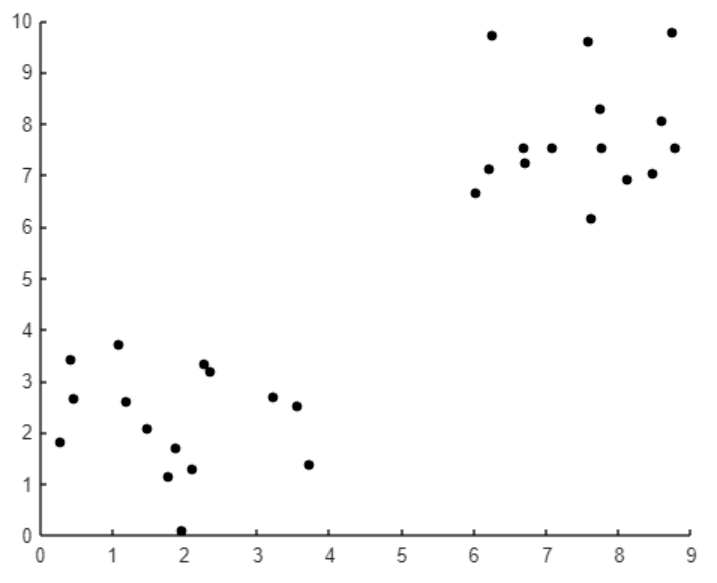            B.   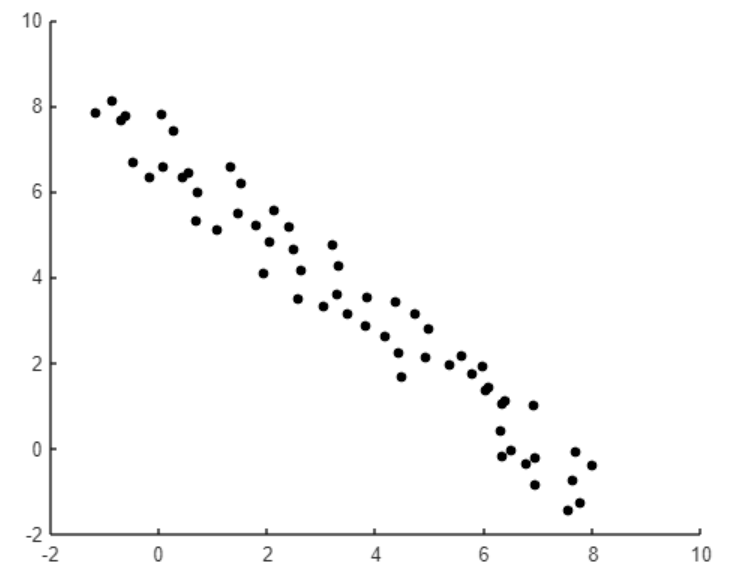

C.   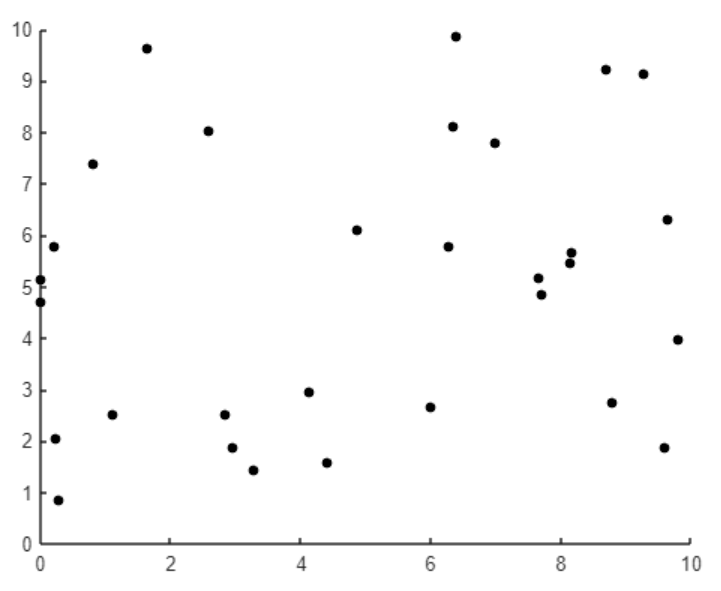            D.   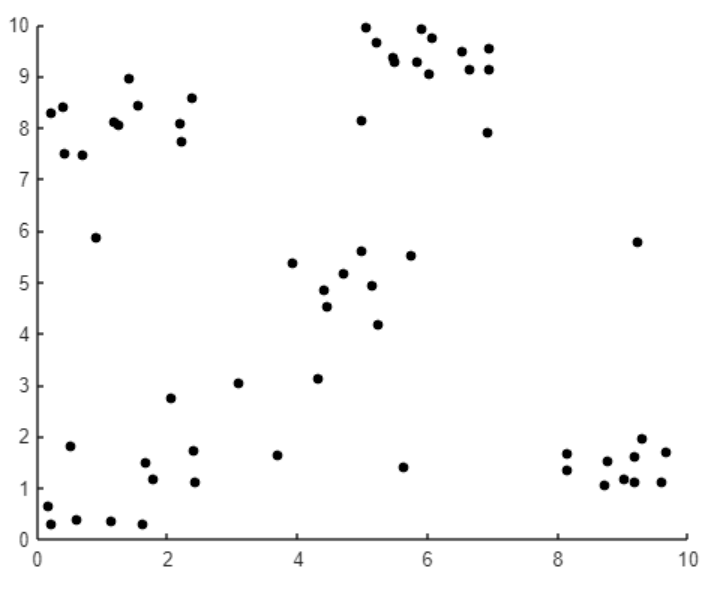

A = false; B = false;
C = false; D = false;
 
CheckExercise1(A, B, C, D);

## **Using k-means to identify penguins**

So far, you've only seen k-means applied to randomly generated data; since the data doesn't mean anything, the results don't either. In this section, you'll apply k-means to real-world data containing culmen measurements for different types of penguins. The culmen is defined as the upper ridge of the beak - for this data, the culmen length and depth are measured as shown in the following image:

*Artwork by @allison_horst*

  **Try**. Use the button below to take a look at the data.

 

warning('off','all');
Data = readtable('PenguinData.csv');
Data.Species = string(Data.Species);
DataTable = Data(:,[3 10 11]);
UnlabeledData = DataTable(:,[2 3])

You should have noticed that some of the data points show "NaN" instead of a number. NaN stands for "Not a Number", and is an indication that there is missing data. There are a variety of ways to handle missing data in MATLAB, which you can read more about [here](https://www.mathworks.com/help/matlab/data_analysis/missing-data-in-matlab.html). In this data set, there are only two missing values out of 344 data points, so let's simply remove those rows from the data and see what it looks like.

  **Try**. Click the button below to remove the missing values and plot the cleaned data.

 

CleanedData = rmmissing(UnlabeledData);
CulmenLength = table2array(CleanedData(:,1));
CulmenDepth = table2array(CleanedData(:,2));
scatter(CulmenLength, CulmenDepth, '.');
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Culmen Measurements for Penguins");

Now that you've gotten a look at the data, try running k-means with some different combinations of parameters. How many clusters do you think there are? Which distance metric works the best for this data? How can you change the parameters such that the algorithm converges in the fewest iterations possible?

  **Try**. Customize your k-means algorithm using the following controls. You can choose to either select your own initial cluster centers or use random ones. Once you have set the parameters as desired, click "Run k-means with these parameters" to see how your algorithm performs on the data.

  **Pro-tip**. For more information about each distance metric, look [here](https://www.mathworks.com/help/stats/kmeans.html#buefs04-Distance).

K = 3;
DistMetric = "sqeuclidean";
MaxIter = 11;
ChooseInitCentroids = false;
 

xCenters = zeros(1,3);
yCenters = zeros(1,3);

if ChooseInitCentroids
    figure;
    scatter(CulmenLength, CulmenDepth, '.');
    xlabel("Culmen Length (mm)");
    ylabel("Culmen Depth (mm)");
    title("Your Initial Centroids");
    for i = 1:K
        [xCenters(i), yCenters(i)] = ginput(1);
        hold on;
        scatter(xCenters(i), yCenters(i), 100, '*', "SeriesIndex", 7);
    end
    hold off;
else
    xCenters = (rand(1,K) * (max(CulmenLength) - min(CulmenLength)) + min(CulmenLength));
    yCenters = (rand(1,K) * (max(CulmenDepth) - min(CulmenDepth)) + min(CulmenDepth));
    disp("Cluster centers have been randomized!");
end
[ClusterIndices,~] = kmeans(table2array(CleanedData), K, 'Distance', DistMetric, 'MaxIter', MaxIter, 'Start', [xCenters' yCenters']);
CulmenData = table2array(CleanedData);
figure;
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Resulting Clusters");
hold on
for idx = 1:5
    plot(CulmenData(ClusterIndices==idx,1), CulmenData(ClusterIndices==idx,2), '.')
    finalCentroids(idx,:) = [mean(CulmenData(ClusterIndices==idx,1)) mean(CulmenData(ClusterIndices==idx,2))];
end
LabelFinal = scatter(finalCentroids(:,1), finalCentroids(:,2), 100, '*', "SeriesIndex", 6);
LabelInit = scatter(xCenters, yCenters, 100, '*', "SeriesIndex", 11);
legend([LabelFinal LabelInit], {'Final Centroids' 'Initial Centroids'});
hold off;

 **Reflect**. It was probably difficult to decide how to customize your algorithm without knowing much about the data. What information would have helped you to make more informed decisions?

### **A closer look at the data**

Let's take another look at the data, this time with labels. You'll see that the data set contains data for three different species of penguins: Adélie, Chinstrap, and Gentoo. You'll also be able to see which data points correspond to which penguin species.

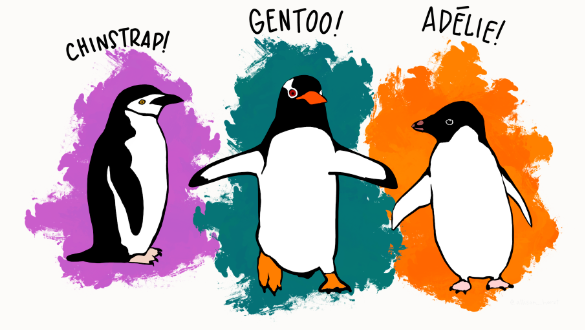

*Artwork by @allison_horst*

  **Try**. Use the button below to visualize the labeled data set.

 

LabeledData = rmmissing(DataTable);
PenguinData = table2array(LabeledData(:,2:3));
PenguinSpecies = table2array(LabeledData(:,1));
shPenguinSpecies = extractBefore(PenguinSpecies," ");
Species = unique(PenguinSpecies);

figure;
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Culmen Measurements for 3 Different Types of Penguins");

hold on
for idx = 1:length(Species)
    plot(PenguinData(PenguinSpecies==Species(idx),1),PenguinData(PenguinSpecies==Species(idx),2),".")
end
hold off

shSpecies = extractBefore(Species," ");
legend(shSpecies)

How does this new information change the way you want to select the parameters for your k-means algorithm? Play around with some different parameters again, this time knowing that there are 3 clusters (this will automatically be used as the *k* value for all of your runs).

  **Try**. Customize your k-means algorithm using the following controls. You can choose to either select your own initial cluster centers or use random ones. Once you have set the parameters as desired, click "Run k-means with these parameters" to see how your algorithm performs on the data!

  **Pro-tip**. For more information about each distance metric, look [here](https://www.mathworks.com/help/stats/kmeans.html#buefs04-Distance).

K = 3;
DistMetric = "sqeuclidean";
MaxIter = 11;
ChooseInitCentroids = false;
 

if ChooseInitCentroids
    figure;
    scatter(CulmenLength, CulmenDepth, '.');
    xlabel("Culmen Length (mm)");
    ylabel("Culmen Depth (mm)");
    title("Your Initial Centroids");
    
    for i = 1:K
        [xCenters(i), yCenters(i)] = ginput(1);
        hold on;
        scatter(xCenters(i), yCenters(i), 100, '*', "SeriesIndex", 7);
    end
    hold off;
else
    xCenters = (rand(1,K) * (max(CulmenLength) - min(CulmenLength)) + min(CulmenLength));
    yCenters = (rand(1,K) * (max(CulmenDepth) - min(CulmenDepth)) + min(CulmenDepth));
    disp("Cluster centers have been randomized!");
end


** The first figure you see will be a plot of the data, color-coded by cluster. The second figure will be a heatmap depicting each data point's assigned cluster vs. its actual label. If the algorithm performs well, each row and each column of the heatmap will have exactly one high count (dark blue square). The more overlap there is between the clusters, the less accurate the algorithm was.*

[ClusterIndices,~] = kmeans(table2array(CleanedData), K, 'Distance', DistMetric, 'MaxIter', MaxIter, 'Start', [xCenters' yCenters']);

CulmenData = table2array(CleanedData);
figure
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Resulting Clusters");
hold on
for idx = 1:5
    plot(CulmenData(ClusterIndices==idx,1), CulmenData(ClusterIndices==idx,2), '.')
    finalCentroids(idx,:) = [mean(CulmenData(ClusterIndices==idx,1)) mean(CulmenData(ClusterIndices==idx,2))];
end
LabelFinal = scatter(finalCentroids(:,1), finalCentroids(:,2), 100, '*', "SeriesIndex", 6);
LabelInit = scatter(xCenters, yCenters, 100, '*', "SeriesIndex", 7);
legend([LabelFinal LabelInit], {'Final Centroids' 'Initial Centroids'});
hold off;

figure;
heatmapTbl = table(ClusterIndices, shPenguinSpecies, 'VariableNames', {'Assigned Cluster', 'Species'});
heatmap(heatmapTbl, "Species", "Assigned Cluster")

*Note: You may have noticed that this method of evaluating clustering results requires labeled data, yet you learned earlier in this script that clustering is typically applied to unlabeled data. If you're wondering how to evaluate clustering methods with unlabeled data, that information will be covered in the next script (*[*ClusteringMethods.mlx*](matlab:open('./ClusteringMethods.mlx'))*).*

 **Exercise. **Which distance metric worked the best for this data set?

Selection = "Squared Euclidean";
 
CheckExercise2(Selection, CleanedData, shPenguinSpecies);

 **Reflect**. Was there any combination of parameters such that every data point was assigned to the correct cluster? What does this tell you about how to interpret the results of a clustering analysis?

## 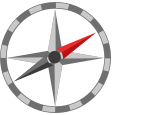Further Exploration

If you are interested, here are some additional resources to help you dive deeper into the topics covered in this live script:

- [Some general resources for clustering in MATLAB](https://www.mathworks.com/discovery/cluster-analysis.html)

- [An example of using k-means to perform color-based segmentation of an image](https://www.mathworks.com/help/images/color-based-segmentation-using-k-means-clustering.html)

In [part 2](matlab:open('Scripts/ClusteringMethods.mlx')) of this module, learn about some different clustering algorithms and how to select the appropriate one for a given problem.

## References

- Horst AM, Hill AP, Gorman KB (2020). palmerpenguins: Palmer Archipelago (Antarctica) penguin data. R package version 0.1.0. https://allisonhorst.github.io/palmerpenguins/. doi: 10.5281/zenodo.3960218.

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

**ShowClustering**

function ShowClustering
% Function to illustrate clustering of data with two features in two groups.

% Generate random data for clustering.
mu1 = [1 2.5];
sigma1 = [1.2 .2; .2 1];
mu2 = [-0.5 -1.2];
sigma2 = [1.15 0; 0 1.1];
X = [mvnrnd(mu1,sigma1,150); mvnrnd(mu2,sigma2,75)];

% Initialize the cluster centers randomly.
ind = randperm(length(X));
X = X(ind,:);
C = X(1:2,:);
C0 = zeros(size(C));

% Initialize plot.
figure("Position",[0 0 600 400]);
plot(X(:,1),X(:,2),"o","MarkerSize",4,"SeriesIndex",1);
title("Clustering","Find groups and patterns")
xlabel("x1");
ylabel("x2");
axis equal manual
hold on
Circle1 = rectangle('Position',[C(1,1)-1.5 C(1,2)-1.5 3 3],'Curvature',[1 1],'FaceColor','none',"SeriesIndex",4);
Circle2 = rectangle('Position',[C(2,1)-1.5 C(2,2)-1.5 3 3],'Curvature',[1 1],'FaceColor','none',"SeriesIndex",5);

% Update the cluster centers by calculating mean distance from all data
% points.
while C ~= C0
    pause(0.5)
    Dist1 = sqrt(sum((X-C(1,:)).^2,2));
    Dist2 = sqrt(sum((X-C(2,:)).^2,2));

    C0 = C;
    C1 = X(Dist1<Dist2,:);
    C2 = X(~(Dist1<Dist2),:);
    C = [mean(C1);mean(C2)];

    Circle1.Position = [C(1,1)-1.5 C(1,2)-1.5 3 3];
    Circle2.Position = [C(2,1)-1.5 C(2,2)-1.5 3 3];
    drawnow
end

% Update the plot with final cluster assignments.
p = plot(C1(:,1),C1(:,2),"o",C2(:,1),C2(:,2),"o","MarkerSize",4);
p(1).SeriesIndex = 4;
p(2).SeriesIndex = 5;
drawnow
hold off
end

**CheckExercise1**

function CheckExercise1(A, B, C, D)
    if A && ~B && ~C && D
        disp("Great job!");
    else
        disp("Try again. Which data sets seem to have separable clusters?");
    end
end

**CheckExercise2**

function CheckExercise2(Selection, CleanedData, shPenguinSpecies)
    if Selection == "Cosine"
        disp("Great job!");
    else
        disp("Try again. Which distance metric resulted in the data being clustered the most accurately?");

        DistMetrics = ["sqeuclidean", "cityblock", "cosine", "correlation"];
        DistMetricTitles = ["Squared Euclidean", "City block", "Cosine", "Correlation"];
        for i = 1:4
            [ClusterIndices,~] = kmeans(table2array(CleanedData), 3, 'Distance', DistMetrics(i));
            subplot(2,2,i);
            HeatmapTbl = table(ClusterIndices, shPenguinSpecies, 'VariableNames', {'Assigned Cluster', 'Species'});
            heatmap(HeatmapTbl, "Species", "Assigned Cluster");
            title(DistMetricTitles(i));
        end
    end
end

Copyright 2023 The MathWorks™, Inc